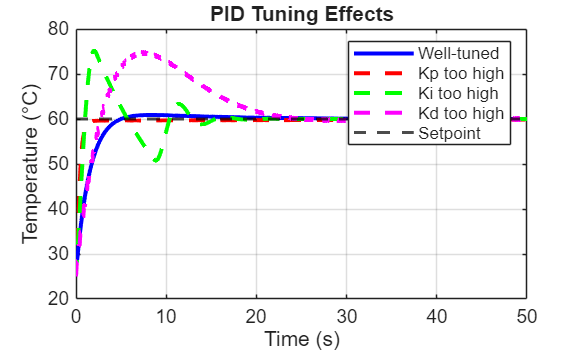

%% PID Tuning Demo

dt = 0.1;
t = 0:dt:50;  % renamed from 'time' to avoid conflict

% System parameters
a = 0.1;
b = 0.5;
T_env = 25;
setpoint = 60;

% Different PID tunings
temps_well = simulate_pid(2.0, 0.2, 1.0, t, a, b, T_env, setpoint);      % well-tuned
temps_kp_high = simulate_pid(10.0, 0.2, 1.0, t, a, b, T_env, setpoint);  % Kp too high → overshoot
temps_ki_high = simulate_pid(2.0, 5.0, 1.0, t, a, b, T_env, setpoint);   % Ki too high → oscillations
temps_kd_high = simulate_pid(2.0, 0.2, 10, t, a, b, T_env, setpoint);   % Kd too high → initial spike, sluggish decay

% Plot
figure;
plot(t, temps_well, 'b', 'LineWidth', 2); hold on
plot(t, temps_kp_high, 'r--', 'LineWidth', 2);
plot(t, temps_ki_high, 'g--', 'LineWidth', 2);
plot(t, temps_kd_high, 'm--', 'LineWidth', 2);
yline(setpoint,'--k','LineWidth',1.5)

xlabel('Time (s)')
ylabel('Temperature (°C)')
title('PID Tuning Effects')
legend('Well-tuned','Kp too high','Ki too high','Kd too high','Setpoint')
grid on


%% Function defined at the end of the script
function temps = simulate_pid(Kp, Ki, Kd, t, a, b, T_env, setpoint)
    dt = t(2) - t(1); % compute dt from t array
    T = 25;
    integral = 0;
    prev_error = 0;
    temps = zeros(size(t));

    for i = 1:length(t)
        error = setpoint - T;
        integral = integral + error*dt;

        if i == 1
            derivative = 0;
        else
            derivative = (error - prev_error)/dt;
        end

        u = Kp*error + Ki*integral + Kd*derivative;
        u = max(0, min(100,u)); % clamp control

        temps(i) = T;           % store before updating
        dTdt = -a*(T - T_env) + b*u;
        T = T + dTdt*dt;

        prev_error = error;
    end
end